### preprocesamiento de datos EMG-CARDEB-MAGMA - grupo bicep [todas las disciplinas]

**Resumen**

El proceso completo comenzo cargando los archivos .wav (EMG crudo, 2000 Hz, 1 canal, 96 sujetos). de entre los cuales se selccionaron aquellos registros que contenian señales EMG correspondientes al bíceps braquial durante ejercicios de levantamiento de mancuernas. Cada serie consistió en 10 repeticiones, sin embargo el objetivo se  centro en la discriminacion de los patrones electrofisiológicos caracteristicos de los estados de reposo y actividad muscular. 

La compatibilidad de los registros se verificó confirmando la uniformidad de 2000 Hz en todos los archivos, la cual fue elegida basandose en el teorema de Nyquist que exije una frecuencia de muestreo de al menos 1000Hz para señales EMG y conforme a los protocolos estadar de adquisicion. de este modo se determino que: las señales son aptas para análisis en dominio temporal.

El procedimiento posterior se basó en un conjunto ampliado de características extraídas de  Hudgins donde ademas de: Valor Absoluto Medio (MAV), Cambios de Pendiente (SSC) y Longitud de Onda (WL); Se incorporaron otras métricas como: Varianza (VAR), Desviación Estándar (STD), Error Medio Cuadrático (RMSE) y Suma de la Amplitud Absoluta (AAS).

**Inicio del preprocesado**

Debido a que se hace uso de registros en formato `.wav`, se asume que los valores de amplitud han sido cuantificados como enteros de 16 bits con signo, con un rango dinámico de –32,768 a +32,767. Por lo tanto, al utilizar la función `audioread()` en MATLAB, la señal es automáticamente convertida al tipo `double` y normalizada al rango de –1 a 1.

Una vez normalizada la señal, es importante considerar las características intrínsecas de la señal electromiográfica para su adecuado tratamiento, en este contexto,  De Luca en *Surface Electromyography: Detection and Recording, *nos deja un pequeño resumen de estas: 

- La amplitud de la señal EMG es de naturaleza estocástica

- Puede representarse razonablemente mediante una función de distribución gaussiana. 

- La amplitud de la señal puede oscilar entre 0 y 10 mVpp o de 0 a 1,5 mVrms. 

- La energía utilizable de la señal se limita al rango de frecuencia de 0 a 500 Hz, 

- La energía dominante ocupa el rango de 50 a 150 Hz.

- Las señales utilizables son aquellas con energía por encima del nivel de ruido eléctrico.

tal y como podemos ver en la figura 1, se presenta un ejemplo caracteristico del espectro de frecuencia de la señal EMG.

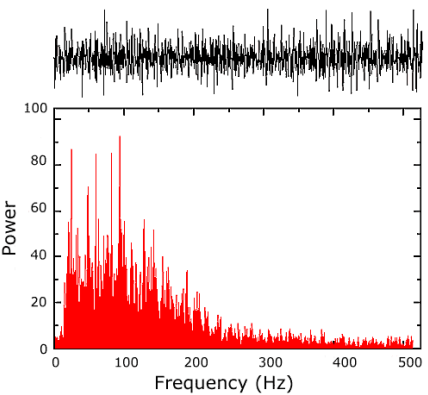

**Fig 1: **Espectro de frecuencias de la señal EMG detectada en el músculo tibial anterior durante una contracción isométrica de fuerza constante al 50 % del máximo voluntario.

Considerando todo esto, fue necesario implementar un preprocesamiento que permitiera aislar la información útil de la actividad muscular respecto al ruido y artefactos. Por lo que se aplicaron los filtros:

- Pasa-banda Butterworth de sexto orden con frecuencias de corte de 50 Hz y 150 Hz. 

- Media móvil con ventana de 500 muestras (250 ms para 2000 Hz).

clear all; close all; clc; addpath("funciones"); Fs = 2000;

exportando 1


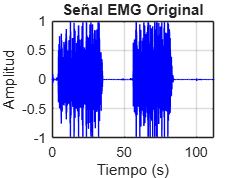

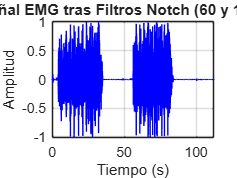

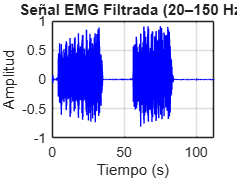

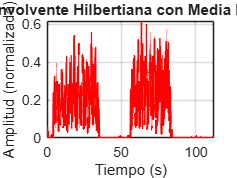

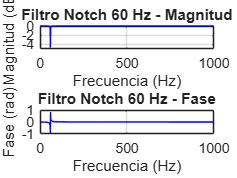

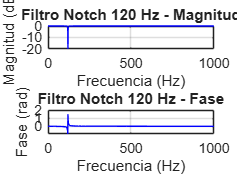

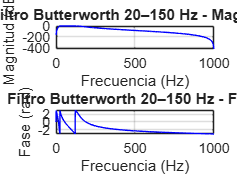

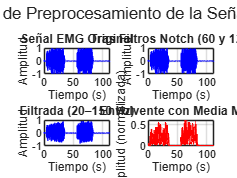

procesar = true;

if (procesar) 
    [fileroute] = scanfolder("dataset"); 

    for i = 1:1 %length(fileroute)
        fprintf('exportando %d\n', i)
        [Cache, ~] = audioread(fileroute(i));
        [Cache] = FILTERING(Cache);
        audiowrite("FILTERING/" + i + ".wav", Cache, Fs);
    end
end

Los parámetros de Hjorth son un conjunto de tres descriptores estadísticos en el dominio del tiempo, introducidos por Bo Hjorth en 1970 para analizar señales complejas como las de electroencefalografía (EEG). 

Las tres características principales de Hjorth son: 

- **Actividad:** Representa la potencia total de la señal o la varianza de la amplitud. Un valor alto indica una señal con mayor energía o amplitud, lo que en el contexto del EEG puede relacionarse con un estado de alerta. Se calcula como la varianza de la señal.

- **Movilidad:** Mide la frecuencia media o la velocidad de cambio de la señal, proporcionando una estimación de la desviación estándar de la pendiente. Es el cociente entre la raíz cuadrada de la varianza de la primera derivada de la señal y la raíz cuadrada de la varianza de la señal original.

- **Complejidad:** Indica la tasa de cambio en la frecuencia y la similitud de la forma de onda con una onda sinusoidal. Se define como el cociente entre la movilidad de la primera derivada y la movilidad de la señal. Un valor de complejidad igual a 1 indica una forma de onda puramente sinusoidal.

Características clave de los parámetros de Hjorth

- **Análisis en el dominio del tiempo:** A diferencia de otros métodos que analizan la señal en el dominio de la frecuencia (como el análisis de espectro), los parámetros de Hjorth se calculan directamente a partir de la señal en el dominio del tiempo, lo que los hace computacionalmente eficientes.

- **Bajo coste computacional:** Su cálculo, basado en la varianza de la señal y sus derivadas, es relativamente sencillo y requiere menos recursos, lo que los hace ideales para el procesamiento en tiempo real.

- **Amplio rango de aplicaciones:** Aunque se desarrollaron inicialmente para el análisis de EEG, sus aplicaciones se han extendido a otros campos como el análisis de señales táctiles en robótica para detectar texturas, el diagnóstico de fallos en maquinaria industrial y el análisis de señales EMG.

- **Correlación con el dominio de la frecuencia:** Aunque se calculan en el dominio del tiempo, estos parámetros tienen un significado correspondiente en el dominio de la frecuencia, lo que permite una interpretación más profunda de las propiedades de la señal.

[fileroute] = scanfolder("FILTERING"); 
all_features = [];

for i = 1:0 %% length(fileroute)
    [Cache, Fs] = audioread(fileroute(i)); 
    features = extractEMGFeatures(Cache, Fs, 500, 50, 0, 0);
    all_features = [all_features; features];
end

disp("Ejemplo")

Ejemplo


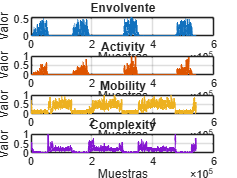

[Cache, Fs] = audioread("FILTERING/10.wav");  
caracteristicas = extractEMGFeatures(Cache, Fs, 500, 50,1,1);
nombres = ["Envolvente", "Activity", "Mobility", "Complexity"];
plotEMGFeatures(caracteristicas, nombres, 4)

Varios estudios han demostrado que estos parámetros son útiles para distinguir entre diferentes estados musculares, como **reposo y contracción** (e.g., *Phinyomark et al., 2012*; *Gazzoni et al., 2004*), incluso sin necesidad de recurrir a transformadas espectrales complejas.

% Temp = array2table(all_features, ...
%     'VariableNames', {'Activity', 'Mobility', 'Complexity'});
% writetable(Temp, 'emg_features.csv');

% Cargar tabla desde el archivo CSV
T = readtable('emg_features.csv');

% Extraer solo las características numéricas (sin encabezados)
X = T{:, {'Activity', 'Mobility', 'Complexity'}};

% Aplicar K-Means con 2 clusters
num_clusters = 2;
[idx, C] = kmeans(X, num_clusters);

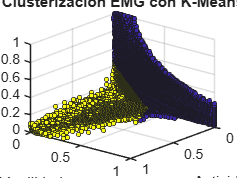

figure
scatter3(X(:,1), X(:,2), X(:,3), 10, idx, 'filled', ...
    'MarkerEdgeColor', [0.1 0.1 0.1], 'LineWidth', 0.5);  

colormap("parula");
xlabel('Actividad'); ylabel('Movilidad'); zlabel('Complejidad');
title('Clusterización EMG con K-Means');
view(130, 25); 

% Añadir columna de cluster a la tabla original
T.Cluster = idx;

% Guardar nueva tabla con cluster incluido
writetable(T, 'emg_features_clustered.csv');

% Ver promedio de cada cluster
cluster1_mean = mean(X(idx == 1, :));
cluster2_mean = mean(X(idx == 2, :));

disp('Media de características por cluster:');

Media de características por cluster:


disp('Cluster 1:'), disp(cluster1_mean)

Cluster 1:
    0.0001    0.4037    0.2562



disp('Cluster 2:'), disp(cluster2_mean)

Cluster 2:
    0.1051    0.1303    0.0367



% Calcular los valores de silueta para cada punto
s = silhouette(X, idx);

% Calcular el coeficiente de silueta promedio
avg_silhouette = mean(s);

% Mostrar resultado
fprintf('Coeficiente de silueta promedio: %.4f\n', avg_silhouette);

Coeficiente de silueta promedio: 0.6648


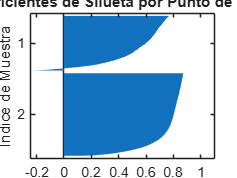

figure;
silhouette(X, idx);
title('Coeficientes de Silueta por Punto de Datos');
xlabel('Coeficiente de Silueta');
ylabel('Índice de Muestra');